# snake

## base

## 33

    something new here

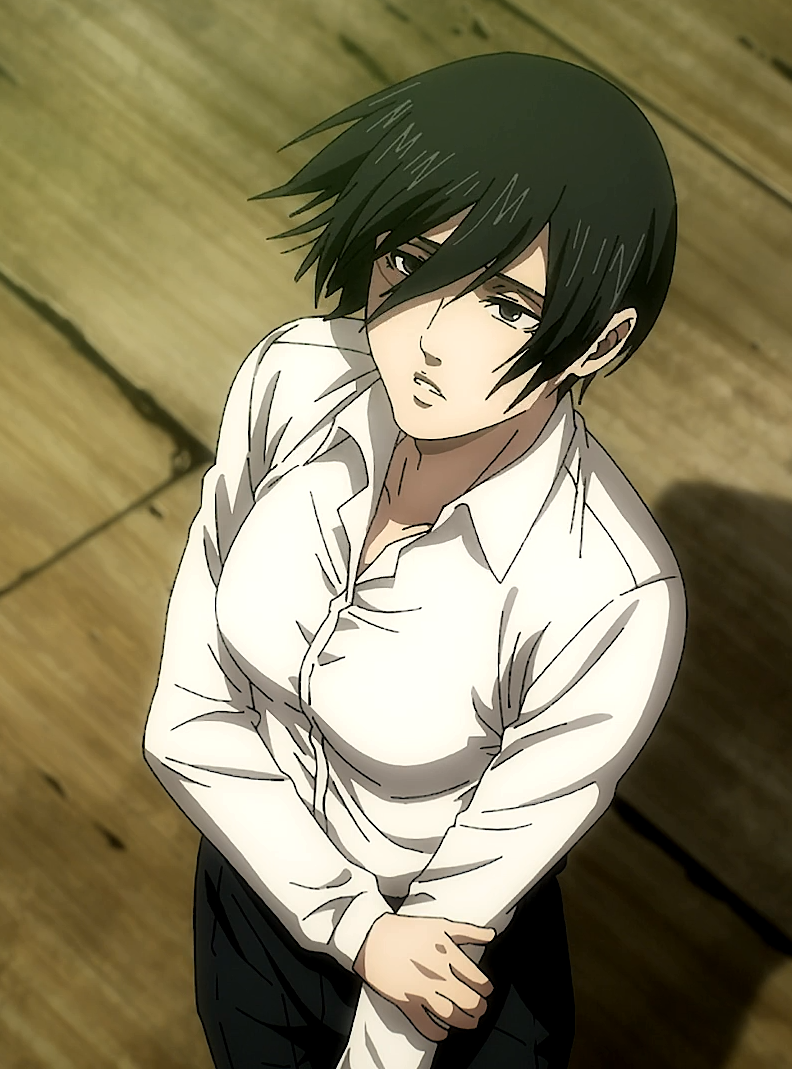

###     dd

%%使用主动轮廓分割图像%%
% close all;       % 关闭当前所有图形窗口，清除工作空间所有变量
% clear all;
% clc;

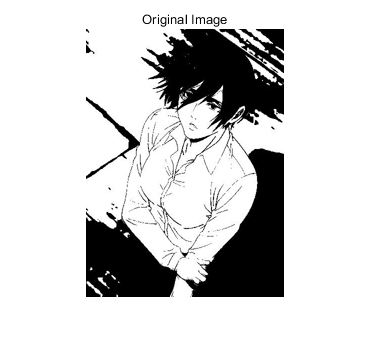


%%读取并显示灰度图像
I_0 = imread('TRY.jpg'); % 1 channel 
I = imresize(I_0,0.5);
figure,imshow(I)%显示图像
title('Original Image')%添加标签

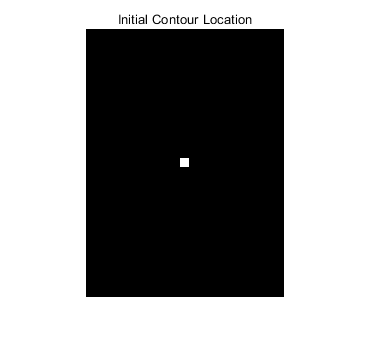


%%指定关注对象周围的初始轮廓。显示该轮廓
mask = zeros(size(I));%初始化一个与I图像一样大小的值都为0的图像mask 0:black

%mask(Y1:Y2,X1:X2),(X1,Y1)为矩形左上角，（X1，Y2）为矩形右下角
BRIM_x = 95; BRIM_y = 130;   % y*x the matrix!
% small mask in the middle can give inner edge of the picture!
mask(BRIM_y:end-BRIM_y,BRIM_x:end-BRIM_x) = 1;
%调整mask区域，x轴为（25~X_max_size-25),y轴为（25~Y_max_size-25)的区域赋值为1（纯白)

figure,imshow(mask)%显示mask图像
title('Initial Contour Location')

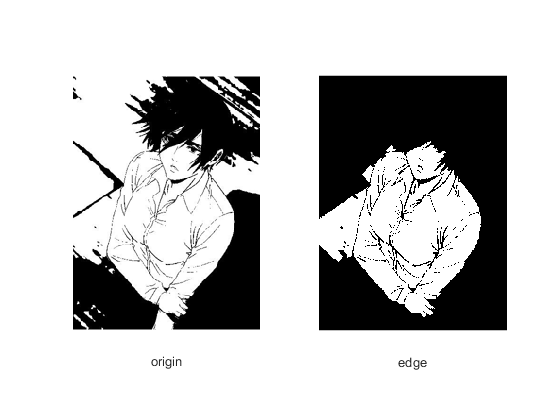


% iteration
edge1 = activecontour(I,mask,400);%调用activecontour函数

figure,
subplot(1,2,1), imshow(I), xlabel('origin');
subplot(1,2,2), imshow(edge1), xlabel('edge'),

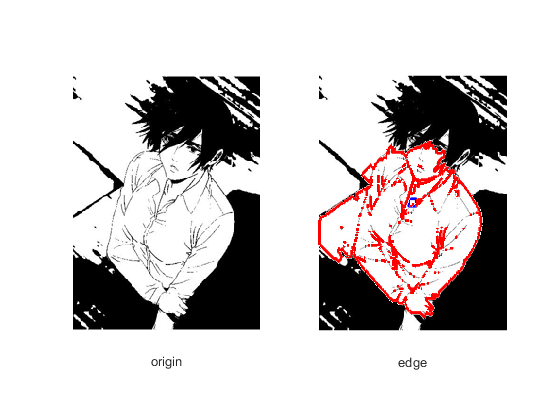



figure,
subplot(1,2,1), imshow(I), xlabel('origin');
subplot(1,2,2), 
imshow(I), xlabel('edge'),
hold on  % to add visualized boundary
visboundaries(mask,'Color','b');  % original mask
visboundaries(edge1,'Color','r');  % new edge

% title('Initial contour (blue) and final contour (red)');





## another try2

for 3 channels RGB?

break into each channel.

maybe multi masks for different area, and combine them!

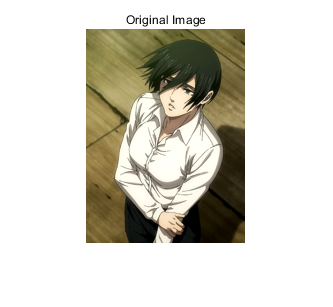

%%读取并显示灰度图像
I_0_2 = imread('mikasa1.png'); % 3 channels
I = imresize(I_0_2, 0.2);
figure,imshow(I)%显示图像
title('Original Image')%添加标签

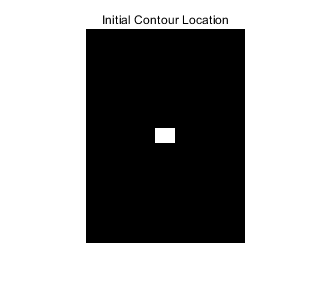


%%指定关注对象周围的初始轮廓。显示该轮廓
mask = zeros(size(I)); % mask  3 channels as well

BRIM_x = 100; BRIM_y = 70;   % x*y the matrix!
% small mask in the middle can give inner edge of the picture!
mask(BRIM_x:end-BRIM_x,BRIM_y:end-BRIM_y, :) = 1;  % 3 channels together!


figure,imshow(mask)%显示mask图像
title('Initial Contour Location')

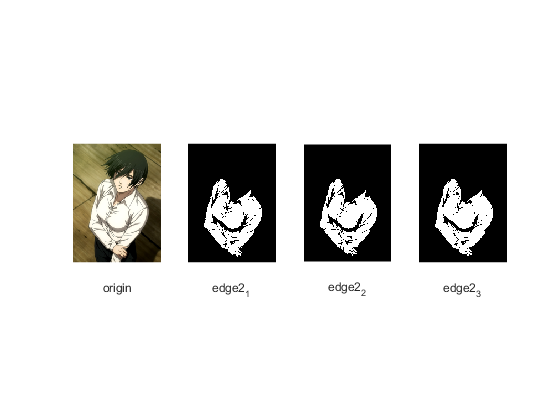



% break into 3 level?
IterTimes = 1000;  % 1000 can be perfect for edge of the garmen!
edge2_1 = activecontour(I(:,:,1),mask(:,:,1),IterTimes);
edge2_2 = activecontour(I(:,:,2),mask(:,:,2),IterTimes);
edge2_3 = activecontour(I(:,:,3),mask(:,:,3),IterTimes);

figure,
subplot(1,4,1), imshow(I), xlabel('origin');
subplot(1,4,2), imshow(edge2_1), xlabel('edge2_1'),
subplot(1,4,3), imshow(edge2_2), xlabel('edge2_2'),
subplot(1,4,4), imshow(edge2_3), xlabel('edge2_3'),

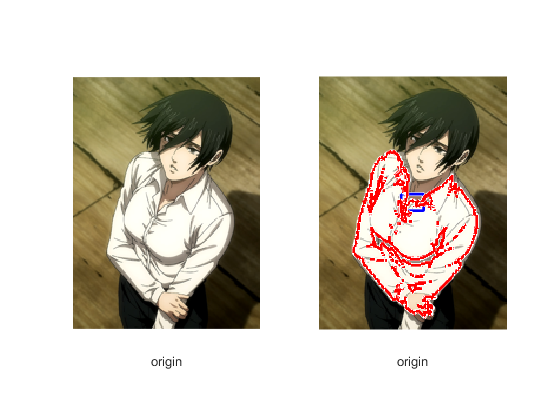




figure,
subplot(1,2,1), imshow(I), xlabel('origin');
subplot(1,2,2), imshow(I), xlabel('origin'),
hold on
% visboundaries(mask,'Color','b');  % original mask
visboundaries(mask(:,:,1),'Color','b');  % original mask
visboundaries(mask(:,:,2),'Color','b');  % original mask
visboundaries(mask(:,:,3),'Color','b');  % original mask

visboundaries(edge2_1,'Color','r');  % new edge
visboundaries(edge2_2,'Color','r');  % new edge
visboundaries(edge2_3,'Color','r');  % new edge5

## combine multi masks for different area

% RGB image
I_0_3 = imread('mikasa1.png'); % 3 channels
I = imresize(I_0_3, 0.2);   
figure,imshow(I)%显示图像
title('Original Image')%添加标签

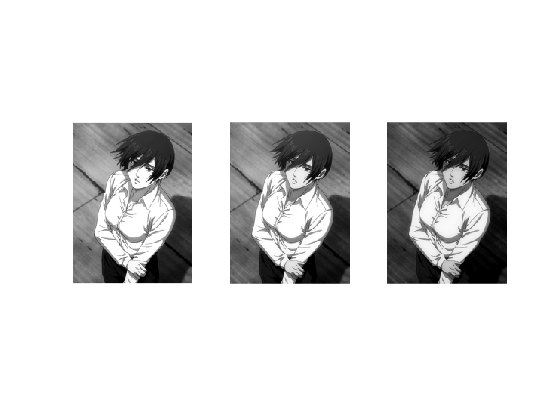


figure,  % breaking into different channel is more clear
subplot(1,3,1), imshow(I(:,:,1));   % first channel is most clear
subplot(1,3,2), imshow(I(:,:,2));
subplot(1,3,3), imshow(I(:,:,3));

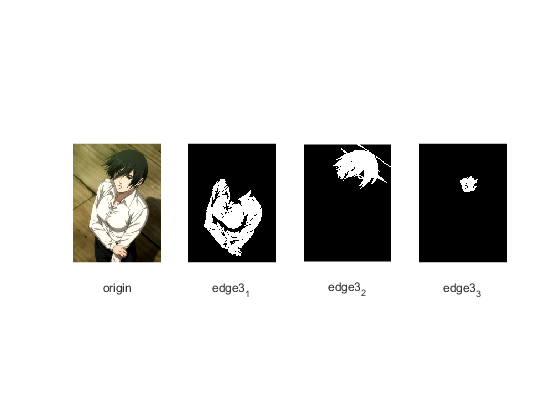


% imwrite(I(:, :, 1), 'try1.png');



% multi masks
mask1 = zeros(size(I(:, : , 1))) ;
mask2 = zeros(size(I(:, : , 1))) ;
mask3 = zeros(size(I(:, : , 1))) ;

% create objection of mask?
mar1_x1 = 100 ; mar1_x2 = 110 ; mar1_y1 = 80 ; mar1_y2 = 85;  % below
mar2_x1 = 45 ; mar2_x2 = 50 ; mar2_y1 = 98 ; mar2_y2 = 100;  % upper
mar3_x1 = 75 ; mar3_x2 = 85 ; mar3_y1 = 90 ; mar3_y2 = 95;    % middle

% tranform to find the "middle" sections!

% matrix : from the left up!
mask1(mar1_x1 : mar1_x2 , mar1_y1: mar1_y2) = 1;
mask2(mar2_x1 : mar2_x2 , mar2_y1: mar2_y2) = 1;
mask3(mar3_x1 : mar3_x2 , mar3_y1: mar3_y2) = 1;


IterTimes2 = 1000;  

% break into 3 level?
edge3_1 = activecontour(I(:,:,1),mask1, IterTimes2);
edge3_2 = activecontour(I(:,:,2),mask2, IterTimes2);
edge3_3 = activecontour(I(:,:,3),mask3, IterTimes2);

figure,
subplot(1,4,1), imshow(I), xlabel('origin');
subplot(1,4,2), imshow(edge3_1), xlabel('edge3_1'),
subplot(1,4,3), imshow(edge3_2), xlabel('edge3_2'),
subplot(1,4,4), imshow(edge3_3), xlabel('edge3_3'),

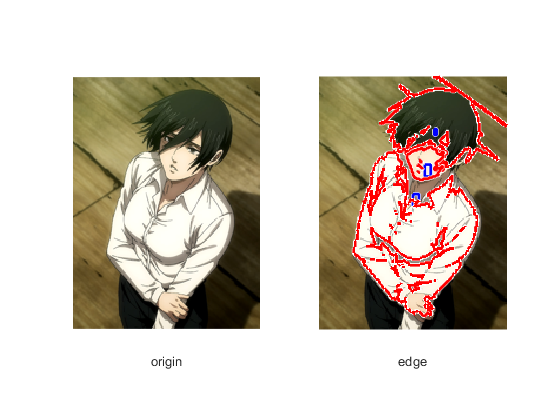




figure,
subplot(1,2,1), imshow(I), xlabel('origin');
subplot(1,2,2), imshow(I), xlabel('edge'),
hold on
% visboundaries(mask,'Color','b');  % original mask
visboundaries(mask1,'Color','b');  % original mask
visboundaries(mask2,'Color','b');  % original mask
visboundaries(mask3,'Color','b');  % original mask

visboundaries(edge3_1,'Color','r');  % new edge
visboundaries(edge3_2,'Color','r');  % new edge
visboundaries(edge3_3,'Color','r');  % new edge5

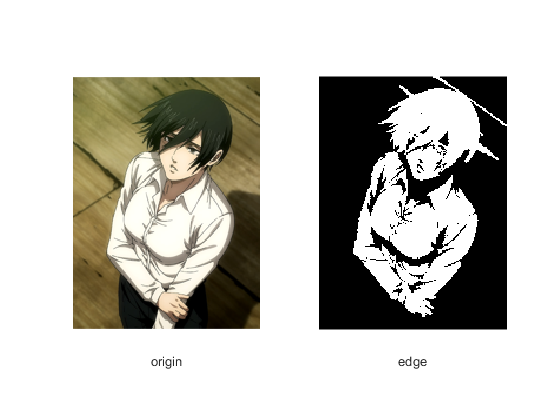



% combine edge
edge3 = edge3_1 + edge3_2 + edge3_3;

figure,
subplot(1,2,1), imshow(I), xlabel('origin');
subplot(1,2,2), imshow(edge3), xlabel('edge'),